# Analysis of the South African sector

#### Coordinates:

coords = [-45,20;-65,20;-45,40;-65,40]; (NW;SW,NE,SE) (lat,lon)

#### Observations:

**Alberello et al. (2019) *****Pancake ice FSD in the Antarctic MIZ.:***

Sector: SA

Measurements: Peak period, SWH, ice concentration, pancake FSD

Dates: 4 July 2017	

**Vichi et al. (2019) **

Sector: SA

Measurements:

Dates: 

#### What is the point?

*Demonstrate the effect of storms on the South African sector. *Observe the general changes from the wind and wave forcing through videos of the ice edge and MIZ. If significant changes are observed "dive-in" and quantify the impacts of these factors.

## Method:

### Storm events:

- Histogram of wind speeds of this sector over the 5 years

- Find the times of the storm events.

- How long do these events last for?

### Waves during of these events:

- What is the wave activitity during these events?

- Are they significantly greater than during non-storm events?

### What are the impacts on the FSD?

- Ice breakup

- Consolidation

- Pancake ice formation

### What are the changes on dynamics?

- Ice speed

- Ice direction

## 1. Preamble

%% Read in the data.
%clear
%close all
addpath functions
addpath packages/quiverwcolorbar

% Parameters
sector = "SA";
grid = 'gx1';
case_name = 'fixedwaves';
filedir = '/Volumes/NoahDay5TB/casesmbp/fixedwaves';

[lat,lon,row] = grid_read(grid);

% Make sector mask
[len,wid] = size(lat);
fig_count = 0;
coords = sector_coords(sector)

coords =    -45    20
   -65    20
   -45    40
   -65    40



day_init = 1;
month_init = 1;
year_init = 2005;
date_init = sprintf('%d-0%d-0%d', year_init, month_init, day_init);
date = date_init;
max_wind = 10;
min_wind = 5;
min_SIC = 0.15;

## Measuring storm events

%% Read in Data
datapoints = 5*365; % days from 01/01/2005-31/12/2009 + 1 leap year

% Take the location to be the centre of the sector
location(1) = (coords(1,1)+coords(2,1))/2;
location(2) = (coords(1,2)+coords(3,2))/2;

[lat_out_north,lon_out] = lat_lon_finder(location(1),location(2),lat,lon); 
[lat_out_south,~] = lat_lon_finder(-80,location(2),lat,lon); 

dim = 2;
for j = 1:datapoints
    filename = strcat(filedir,"/history/iceh.",date,".nc");
    % Find the edge of the MIZ
    variable = "aice";
    aice_data = data_format(filename,variable,row,lat,lon,dim);
    lat_out = lat_out_north;
    for l = lat_out_south:lat_out_north
        if aice_data(lon_out,l) > min_SIC
            ice_edge_pos = l; 
        end
    end
    % Wind speed
    variable = "uatm";
    atm_data_x = data_format(filename,variable,row,lat,lon,dim);
    variable = "vatm";
    atm_data_y = data_format(filename,variable,row,lat,lon,dim);

    atm_x = atm_data_x(lon_out,ice_edge_pos);
    atm_y = atm_data_y(lon_out,ice_edge_pos);

    wind_speed(j) = norm([atm_x,atm_y]);
    wind_direction(j) = atan(atm_y/atm_x);

    date = update_date(date);
end
end_date = date;

## Plotting

date = end_date;

datapoints = 5*365;
% Wind speed
t1 = datetime(year_init,month_init,day_init);
t2 = datetime(str2num(end_date(1:4)),str2num(end_date(6:7)),str2num(end_date(9:10)));
dates = datevec(t1:t2);

ts1 = timeseries(wind_speed,1:datapoints);
ts1.Name = 'Forcing wind speed';
ts1.TimeInfo.Units = 'days';
ts1.TimeInfo.StartDate = char(t1);     % Set start date.
ts1.TimeInfo.Format = 'dd mmm yy';       % Set format for display on x-axis.

ts2 = timeseries(wind_direction,1:datapoints);
ts2.Name = 'Wind direction';
ts2.TimeInfo.Units = 'days';
ts2.TimeInfo.StartDate = char(t1);     % Set start date.
ts2.TimeInfo.Format = 'dd mmm yy';       % Set format for display on x-axis.


%% Plotting
line_width = 1;

% Wind speed
fig_count = fig_count + 1;
figure(fig_count)
plot(ts1,'LineWidth',line_width)
yline(max_wind)


% Wind direction
fig_count = fig_count + 1;
figure(fig_count)
plot(ts2,'LineWidth',line_width)

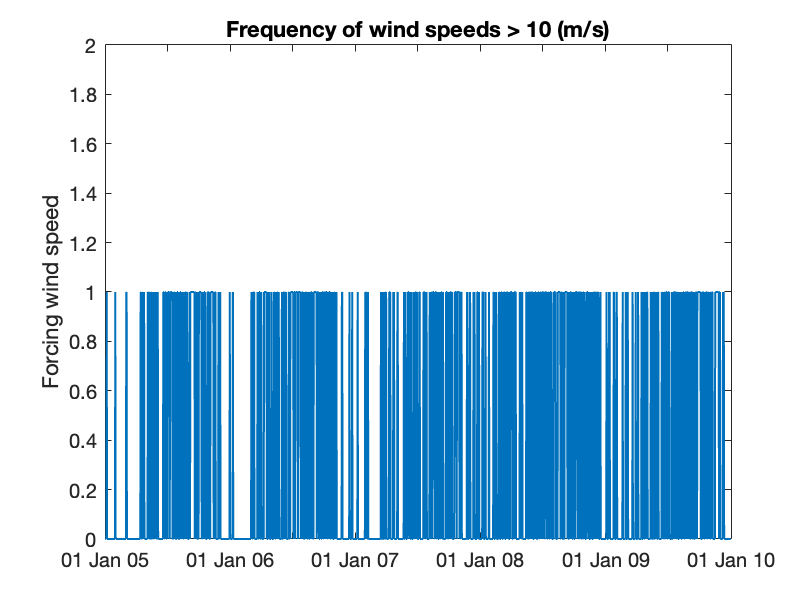


% Storm events
freq_wind = wind_speed > max_wind;


ts3 = timeseries(freq_wind,1:datapoints);
ts3.Name = 'Forcing wind speed';
ts3.TimeInfo.Units = 'days';
ts3.TimeInfo.StartDate = char(t1);     % Set start date.
ts3.TimeInfo.Format = 'dd mmm yy';       % Set format for display on x-axis.

% Wind speed
fig_count = fig_count + 1;
figure(fig_count)
plot(ts3,'LineWidth',line_width)
title(sprintf('Frequency of wind speeds > %g (m/s)',max_wind))
ylim([0,2])

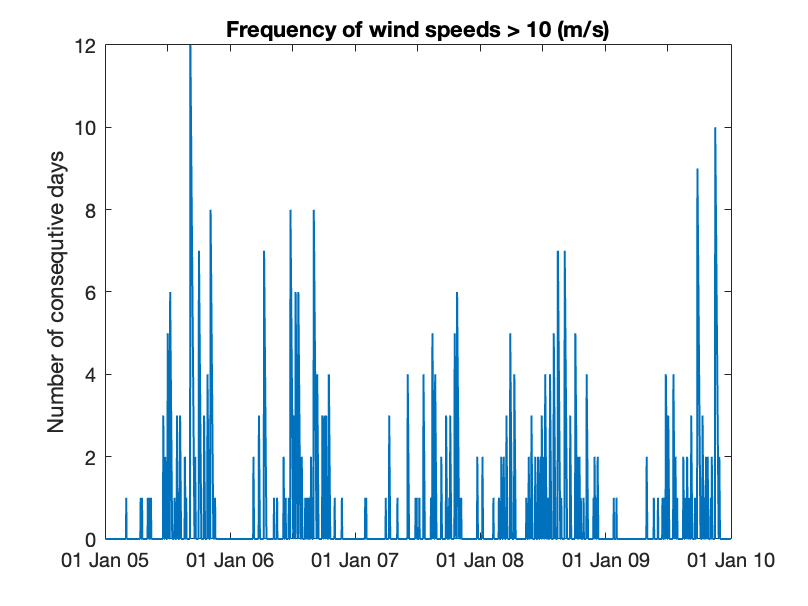


v = numel(freq_wind):-1:1;
ii = [true,diff(freq_wind)~=0];
n = v(ii);
t = [n(2:end)+1,1];
storm_duration = v - t(cumsum(ii));
% remove zeros
storm_duration = storm_duration.*freq_wind;

ts4 = timeseries(storm_duration,1:datapoints);
ts4.Name = 'Number of consequtive days';
ts4.TimeInfo.Units = 'days';
ts4.TimeInfo.StartDate = char(t1);     % Set start date.
ts4.TimeInfo.Format = 'dd mmm yy';       % Set format for display on x-axis.

% Wind speed
fig_count = fig_count + 1;
figure(fig_count)

plot(ts4,'LineWidth',line_width)
title(sprintf('Frequency of wind speeds > %g (m/s)',max_wind))


sprintf('The longest duration of consequential days with winds < %g m/s is %g', max_wind, max(storm_duration))

ans = 'The longest duration of consequential days with winds < 10 m/s is 12'


% When is this storm event?
storm_start = find(storm_duration == max(storm_duration));
storm_end = storm_start + max(storm_duration);

date = date_init;
for i = 1:storm_start
    storm_start_date = date;
    date = update_date(date);
end

for i = 1:storm_end-storm_start
    storm_end_date = date;
    date = update_date(date);
end

daybuffer = 3;

t1 = datetime(str2num(storm_start_date(1:4)),str2num(storm_start_date(6:7)),str2num(storm_start_date(9:10))-daybuffer)

t1 = datetime
   03-Sep-2005


t2 = datetime(str2num(storm_end_date(1:4)),str2num(storm_end_date(6:7)),str2num(storm_end_date(9:10))+daybuffer)

t2 = datetime
   21-Sep-2005





ts5 = timeseries(wind_speed(storm_start-daybuffer:storm_end+daybuffer),1:numel(wind_speed(storm_start-daybuffer:storm_end+daybuffer)));
ts5.Name = 'Wind speed (m/s)';
ts5.TimeInfo.Units = 'days';
ts5.TimeInfo.StartDate = char(t1);     % Set start date.
ts5.TimeInfo.Format = 'dd mmm yy';       % Set format for display on x-axis.








% Wind speed during storm
fig_count = fig_count + 1;
figure(fig_count)
plot(ts5,'LineWidth',line_width)
title('Wind speeds during the longest storm (m/s)')
xline(daybuffer)
xline(storm_end-(storm_start-daybuffer))
grid on


og_storm_start = storm_start;
storm_start = storm_start -daybuffer;
og_storm_end = storm_end;
storm_end = storm_end + daybuffer;

% Regular storm dates
%t1 = datetime(str2num(storm_start_date(1:4)),str2num(storm_start_date(6:7)),str2num(storm_start_date(9:10)))
%t2 = datetime(str2num(storm_end_date(1:4)),str2num(storm_end_date(6:7)),str2num(storm_end_date(9:10)))

storm_direction = wind_direction(storm_start:storm_end).*(360/pi);
ts6 = timeseries(storm_direction,1:numel(storm_direction));
ts6.Name = 'Degrees [-180,180]';
ts6.TimeInfo.Units = 'days';
ts6.TimeInfo.StartDate = char(t1);     % Set start date.
ts6.TimeInfo.Format = 'dd mmm yy';       % Set format for display on x-axis.

% Wind speed during storm
fig_count = fig_count + 1;
figure(fig_count)

plot(ts6,'LineWidth',line_width)
title('Wind direction during the longest storm (m/s)')
ylim([-180,180])
xline(daybuffer)
xline(storm_end-storm_start-daybuffer)
grid on

#### Storm lull comparison

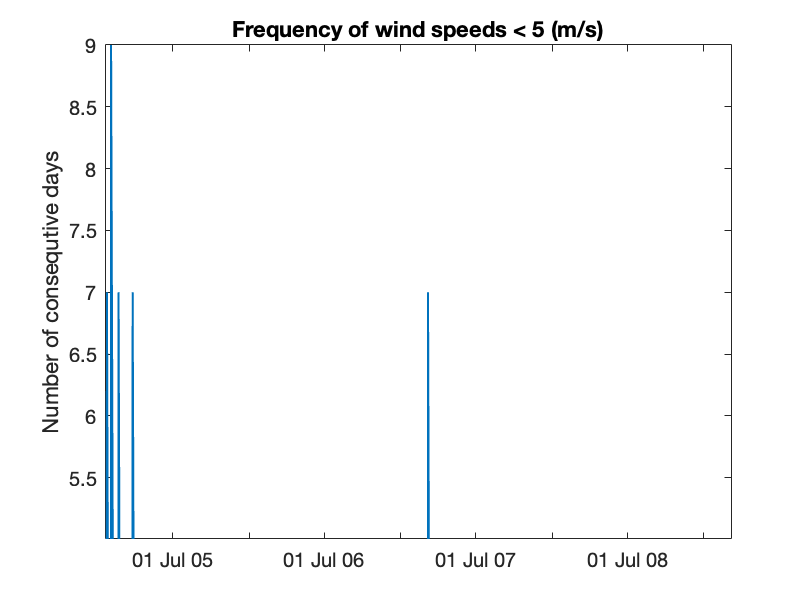

% freq_small_wind = wind_speed < min_wind;
% % Storm lull for comparison
% time1 = datetime(year_init,month_init,day_init);
% time2 = datetime(str2num(end_date(1:4)),str2num(end_date(6:7)),str2num(end_date(9:10)));
% dates = datevec(time1:time2);
% 
% v = numel(freq_small_wind):-1:1;
% ii = [true,diff(freq_small_wind)~=0];
% n = v(ii);
% t = [n(2:end)+1,1];
% lull_duration = v - t(cumsum(ii));
% % remove zeros
% lull_duration = lull_duration.*freq_small_wind;
% 
% ts7 = timeseries(lull_duration,1:datapoints);
% ts7.Name = 'Number of consequtive days';
% ts7.TimeInfo.Units = 'days';
% ts7.TimeInfo.StartDate = char(time1);     % Set start date.
% ts7.TimeInfo.Format = 'dd mmm yy';       % Set format for display on x-axis.
% 
% % Wind speed
% fig_count = fig_count + 1;
% figure(fig_count)
% 
% plot(ts7,'LineWidth',line_width)
% title(sprintf('Frequency of wind speeds < %g (m/s)',min_wind))
% 

% sprintf('The longest duration of consequential days with winds < %g m/s is %g', max_wind, max(storm_duration))
% 

ans = 'The longest duration of consequential days with winds < 10 m/s is 12'

% % When is this storm event?
% lull_start = find(lull_duration == max(lull_duration));
% lull_end = lull_start + max(lull_duration);
% 
% date = date_init;
% for i = 1:lull_start
%     lull_start_date = date;
%     date = update_date(date);
% end
% 
% for i = 1:lull_end-lull_start
%     lull_end_date = date;
%     date = update_date(date);
% end
% 
% daybuffer = 3;
% 
% t1_lull = datetime(str2num(lull_start_date(1:4)),str2num(lull_start_date(6:7)),str2num(lull_start_date(9:10))-daybuffer)
% t2_lull = datetime(str2num(lull_end_date(1:4)),str2num(lull_end_date(6:7)),str2num(lull_end_date(9:10))+daybuffer)

t1_lull = datetime
   29-Jan-2005


% 

t2_lull = datetime
   13-Feb-2005




% ts5 = timeseries(wind_speed(storm_start-daybuffer:storm_end+daybuffer),1:numel(wind_speed(storm_start-daybuffer:storm_end+daybuffer)));
% ts5.Name = 'Wind speed (m/s)';
% ts5.TimeInfo.Units = 'days';
% ts5.TimeInfo.StartDate = char(t1);     % Set start date.
% ts5.TimeInfo.Format = 'dd mmm yy';       % Set format for display on x-axis.
% 
% 
% % Wind speed during storm
% fig_count = fig_count + 1;
% figure(fig_count)
% plot(ts5,'LineWidth',line_width)
% title('Wind speeds during the longest storm (m/s)')
% xline(daybuffer)
% xline(storm_end-(storm_start-daybuffer))
% grid on
% 
% og_storm_start = storm_start;
% storm_start = storm_start -daybuffer;
% og_storm_end = storm_end;
% storm_end = storm_end + daybuffer;
% 
% % Regular storm dates
% %t1 = datetime(str2num(storm_start_date(1:4)),str2num(storm_start_date(6:7)),str2num(storm_start_date(9:10)))
% %t2 = datetime(str2num(storm_end_date(1:4)),str2num(storm_end_date(6:7)),str2num(storm_end_date(9:10)))
% 
% storm_direction = wind_direction(storm_start:storm_end).*(360/pi);
% ts6 = timeseries(storm_direction,1:numel(storm_direction));
% ts6.Name = 'Degrees [-180,180]';
% ts6.TimeInfo.Units = 'days';
% ts6.TimeInfo.StartDate = char(t1);     % Set start date.
% ts6.TimeInfo.Format = 'dd mmm yy';       % Set format for display on x-axis.
% 
% % Wind speed during storm
% fig_count = fig_count + 1;
% figure(fig_count)
% 
% plot(ts6,'LineWidth',line_width)
% title('Wind direction during the longest storm (m/s)')
% ylim([-180,180])
% xline(daybuffer)
% xline(storm_end-storm_start-daybuffer)
% grid on


## Waves during this storm event

date_storm = storm_start_date;
ice_drift_speed = 0;
ice_direction = 0;
sigP = 0;
fsdrad = 0;
swh = 0;
aice = 0;
for j = 1:storm_end-storm_start
    filename = strcat(filedir,"/history/iceh.",date_storm,".nc");
    % Find the edge of the MIZ
    variable = "aice";
    aice_data = data_format(filename,variable,row,lat,lon,dim);
    lat_out = lat_out_north;
    for l = lat_out_south:lat_out_north
        if aice_data(lon_out,l) > min_SIC
            ice_edge_pos = l; 
        end
    end     
    edge_location(j) = lat(lon_out,ice_edge_pos);
    % Drift speed
    variable = "uvel";
    ice_data_x = data_format(filename,variable,row,lat,lon,dim);
    variable = "vvel";
    ice_data_y = data_format(filename,variable,row,lat,lon,dim);

    ice_x = ice_data_x(lon_out,ice_edge_pos);
    ice_y = ice_data_y(lon_out,ice_edge_pos);

    ice_drift_speed(j) = norm([ice_x,ice_y]);

    ice_direction(j) = atan(ice_y/ice_x);

    % Ice concentration
    aice(j) = aice_data(lon_out,ice_edge_pos);

    % Internal stresses
    variable = "sigP";
    sigP_data = data_format(filename,variable,row,lat,lon,dim);
    sigP(j) = sigP_data(lon_out,ice_edge_pos);
    
    % FSD radius
    variable = "fsdrad";
    fsdrad_data = data_format(filename,variable,row,lat,lon,dim);
    fsdrad(j) = fsdrad_data(lon_out,ice_edge_pos);

    % SWH
    variable = "wave_sig_ht";
    swh_data = data_format(filename,variable,row,lat,lon,dim);
    swh(j) = swh_data(lon_out,ice_edge_pos);


    % Look at ~100km into the pack
    hundo_km_in = ice_edge_pos-2;

    ice_x = ice_data_x(lon_out,hundo_km_in);
    ice_y = ice_data_y(lon_out,hundo_km_in);
    ice_drift_speed_hundo_km_in(j) = norm([ice_x,ice_y]);
    ice_direction_hundo_km_in(j) = atan(ice_y/ice_x);
    aice_hundo_km_in(j) = aice_data(lon_out,hundo_km_in);
    sigP_hundo_km_in(j) = sigP_data(lon_out,hundo_km_in);
    fsdrad_hundo_km_in(j) = fsdrad_data(lon_out,hundo_km_in);
    swh_hundo_km_in(j) = swh_data(lon_out,hundo_km_in);

    % Look another ~100 km into the pack
    hundo_km_in = ice_edge_pos-4;

    ice_x = ice_data_x(lon_out,hundo_km_in);
    ice_y = ice_data_y(lon_out,hundo_km_in);
    ice_drift_speed_2hundo_km_in(j) = norm([ice_x,ice_y]);
    ice_direction_2hundo_km_in(j) = atan(ice_y/ice_x);
    aice_2hundo_km_in(j) = aice_data(lon_out,hundo_km_in);
    sigP_2hundo_km_in(j) = sigP_data(lon_out,hundo_km_in);
    fsdrad_2hundo_km_in(j) = fsdrad_data(lon_out,hundo_km_in);
    swh_2hundo_km_in(j) = swh_data(lon_out,hundo_km_in);

    
    data_dates(j) = convertCharsToStrings(date_storm);
    date_storm = update_date(date_storm);
end
pre_storm_post = [ones(1,daybuffer),2*ones(1,storm_end-storm_start-2*daybuffer),3*ones(1,daybuffer)];
T_0 = table(data_dates,ice_drift_speed,ice_direction,aice,sigP,fsdrad,swh,edge_location,pre_storm_post);
T_100 = table(data_dates,ice_drift_speed_hundo_km_in,ice_direction_hundo_km_in,aice_hundo_km_in,sigP_hundo_km_in,fsdrad_hundo_km_in,swh_hundo_km_in,edge_location,pre_storm_post);
T_200 = table(data_dates,ice_drift_speed_2hundo_km_in,ice_direction_2hundo_km_in,aice_2hundo_km_in,sigP_2hundo_km_in,fsdrad_2hundo_km_in,swh_2hundo_km_in,edge_location,pre_storm_post);
T_0 = renamevars(T_0,["data_dates","ice_drift_speed","ice_direction","aice","sigP","fsdrad" ...
    ,"swh","edge_location","pre_storm_post"],["dates", "drift_speed", "drift_direction", "aice","sigP","fsd","edge_location","storm_stages"])

Error using tabular/renamevars (line 60)
The number of new variable names must match the number of variables specified.

T_100 = renamevars(T_100,["data_dates","ice_drift_speed_hundo_km_in","ice_direction_hundo_km_in","aice_hundo_km_in","sigP_hundo_km_in","fsdrad_hundo_km_in" ...
    ,"swh_hundo_km_in","edge_location","pre_storm_post"],["dates", "drift_speed", "drift_direction", "aice","sigP","fsd","edge_location","storm_stages"])
T_200 = renamevars(T_200,["data_dates","ice_drift_speed_2hundo_km_in","ice_direction_2hundo_km_in","aice_2hundo_km_in","sigP_2hundo_km_in","fsdrad_2hundo_km_in" ...
    ,"swh_2hundo_km_in","edge_location","pre_storm_post"],["dates", "drift_speed", "drift_direction", "aice","sigP","fsd","edge_location","storm_stages"])

## Plotting time series over storm

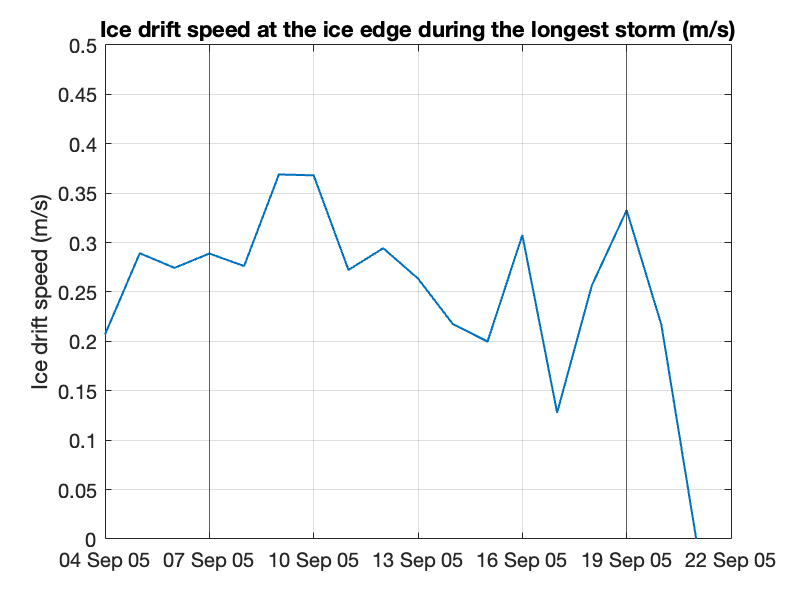

dist_into_miz = lldistkm([lat(lon_out,ice_edge_pos), lon(lon_out,ice_edge_pos)],[lat(lon_out,ice_edge_pos-2), lon(lon_out,ice_edge_pos-2)]);
dist_into_miz2 = lldistkm([lat(lon_out,ice_edge_pos), lon(lon_out,ice_edge_pos)],[lat(lon_out,ice_edge_pos-4), lon(lon_out,ice_edge_pos-4)]);
%t1 = datetime(str2num(storm_start_date(1:4)),str2num(storm_start_date(6:7)),str2num(storm_start_date(9:10)));
%t2 = datetime(str2num(storm_end_date(1:4)),str2num(storm_end_date(6:7)),str2num(storm_end_date(9:10)));

% Ice drift
storm_ts1 = timeseries(ice_drift_speed,1:numel(ice_drift_speed));
storm_ts1.Name = 'Ice drift speed (m/s)';
storm_ts1.TimeInfo.Units = 'days';
storm_ts1.TimeInfo.StartDate = char(t1);     % Set start date.
storm_ts1.TimeInfo.Format = 'dd mmm yy';       % Set format for display on x-axis.

fig_count = fig_count + 1;
figure(fig_count)

plot(storm_ts1,'LineWidth',line_width)
title('Ice drift speed at the ice edge during the longest storm (m/s)')
ylim([0,0.5])
xline(daybuffer)
xline(storm_end-storm_start-daybuffer)
grid on

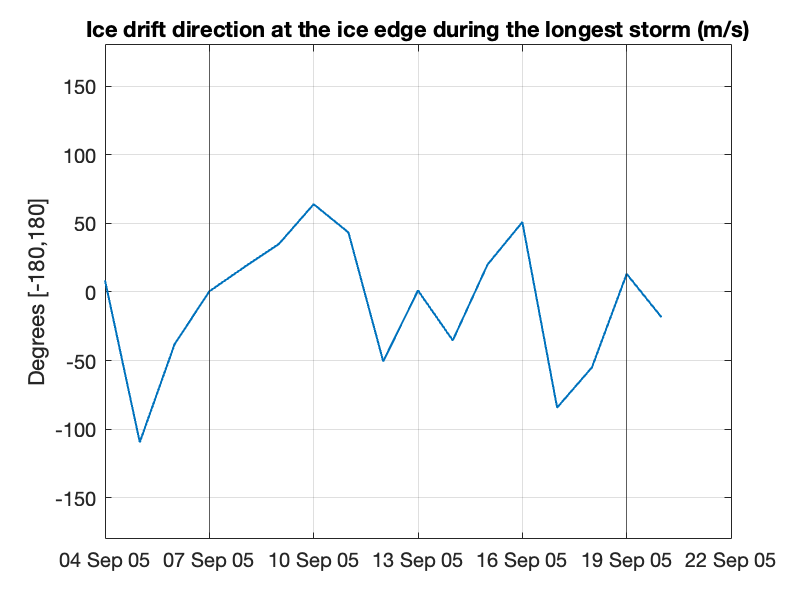


% Ice direction
storm_ts2 = timeseries(ice_direction*(360/pi),1:numel(ice_direction));
storm_ts2.Name = 'Degrees [-180,180]';
storm_ts2.TimeInfo.Units = 'days';
storm_ts2.TimeInfo.StartDate = char(t1);     % Set start date.
storm_ts2.TimeInfo.Format = 'dd mmm yy';       % Set format for display on x-axis.

fig_count = fig_count + 1;
figure(fig_count)

plot(storm_ts2,'LineWidth',line_width)
title('Ice drift direction at the ice edge during the longest storm (m/s)')
ylim([-180,180])
xline(daybuffer)
xline(storm_end-storm_start-daybuffer)
grid on

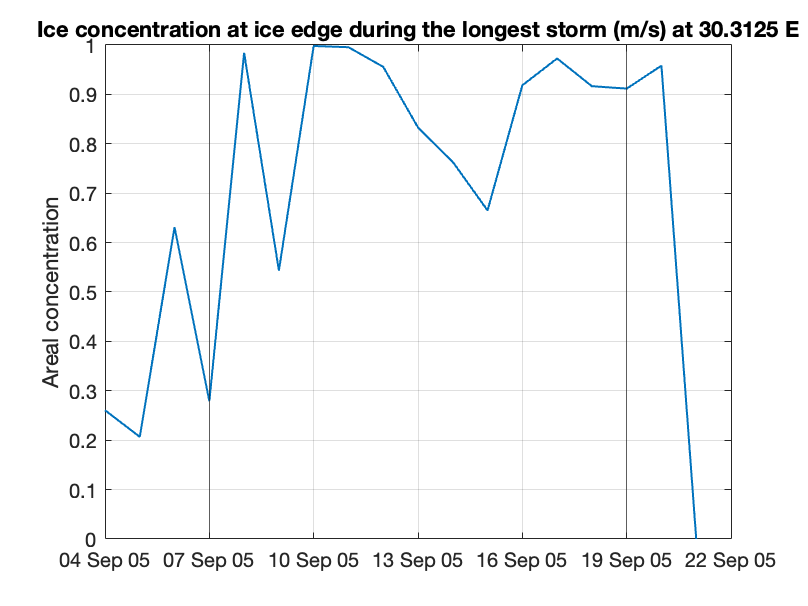


% Aice

storm_ts3 = timeseries(aice,1:numel(aice));
storm_ts3.Name = 'Areal concentration';
storm_ts3.TimeInfo.Units = 'days';
storm_ts3.TimeInfo.StartDate = char(t1);     % Set start date.
storm_ts3.TimeInfo.Format = 'dd mmm yy';       % Set format for display on x-axis.

fig_count = fig_count + 1;
figure(fig_count)

plot(storm_ts3,'LineWidth',line_width)
title(sprintf('Ice concentration at ice edge during the longest storm (m/s) at %g E', lon(lon_out,1)))
ylim([0,1])
xline(daybuffer)
xline(storm_end-storm_start-daybuffer)
grid on

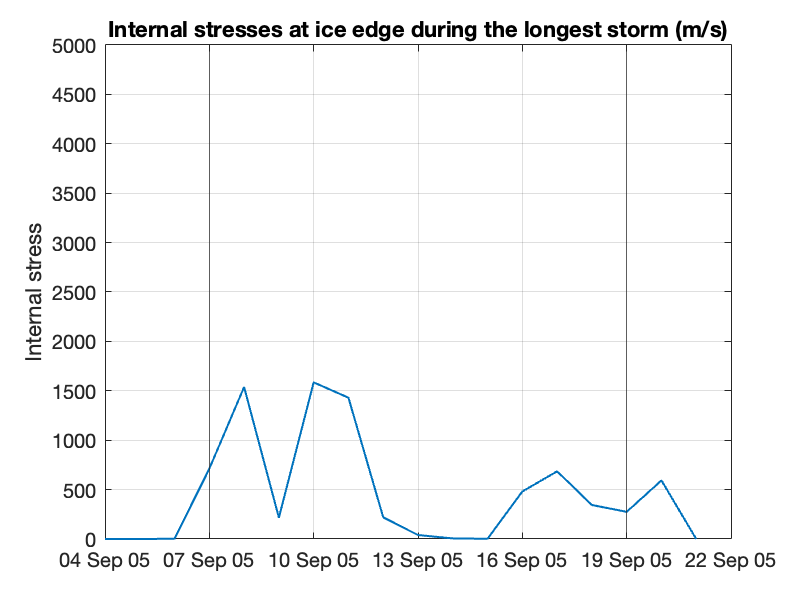


% Internal stress

storm_ts4 = timeseries(sigP,1:numel(aice));
storm_ts4.Name = 'Internal stress';
storm_ts4.TimeInfo.Units = 'days';
storm_ts4.TimeInfo.StartDate = char(t1);     % Set start date.
storm_ts4.TimeInfo.Format = 'dd mmm yy';       % Set format for display on x-axis.

fig_count = fig_count + 1;
figure(fig_count)

plot(storm_ts4,'LineWidth',line_width)
title(sprintf('Internal stresses at ice edge during the longest storm (m/s)',lon(lon_out,1)))
ylim([0,5000])
xline(daybuffer)
xline(storm_end-storm_start-daybuffer)
grid on

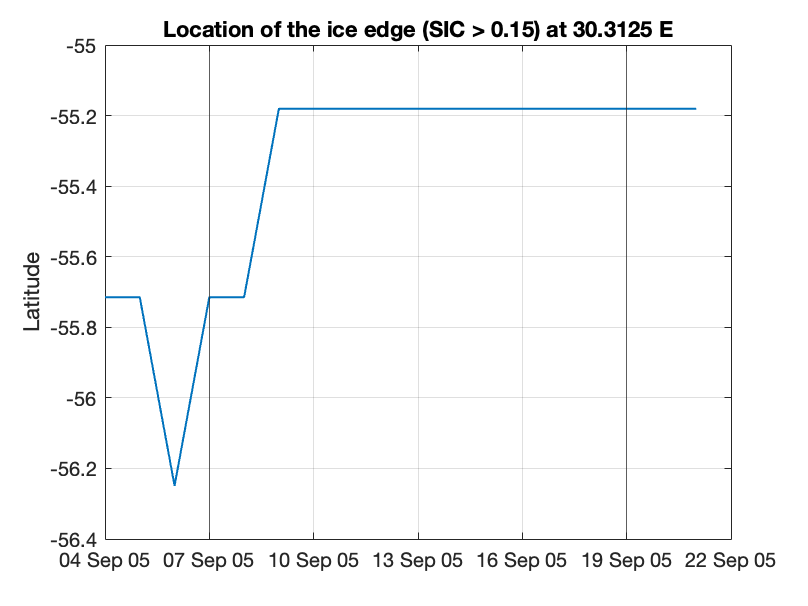


% Ice edge location

storm_ts5 = timeseries(ice_edge_data.edge_location,1:numel(ice_edge_data.edge_location));
storm_ts5.Name = 'Latitude';
storm_ts5.TimeInfo.Units = 'days';
storm_ts5.TimeInfo.StartDate = char(t1);     % Set start date.
storm_ts5.TimeInfo.Format = 'dd mmm yy';       % Set format for display on x-axis.

fig_count = fig_count + 1;
figure(fig_count)

plot(storm_ts5,'LineWidth',line_width)
title(sprintf('Location of the ice edge (SIC > %g) at %g E',min_SIC, lon(lon_out,1)))
xline(daybuffer)
xline(storm_end-storm_start-daybuffer)
%ylim([0,5000])
grid on

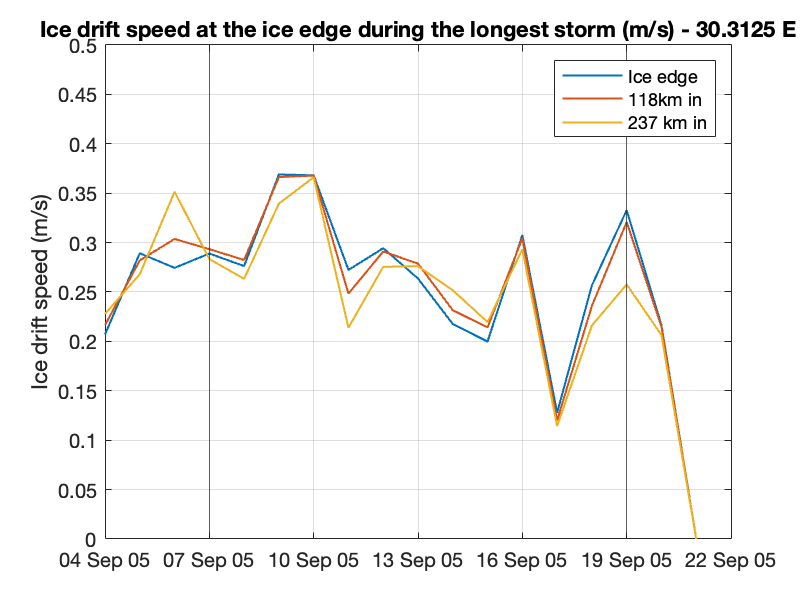




% 100 km in


%t1 = datetime(str2num(storm_start_date(1:4)),str2num(storm_start_date(6:7)),str2num(storm_start_date(9:10)));
%t2 = datetime(str2num(storm_end_date(1:4)),str2num(storm_end_date(6:7)),str2num(storm_end_date(9:10)));

% Ice drift
storm_ts10 = timeseries(ice_drift_speed_hundo_km_in,1:numel(ice_drift_speed_hundo_km_in));
storm_ts10.Name = 'Ice drift speed (m/s)';
storm_ts10.TimeInfo.Units = 'days';
storm_ts10.TimeInfo.StartDate = char(t1);     % Set start date.
storm_ts10.TimeInfo.Format = 'dd mmm yy';       % Set format for display on x-axis.

storm_ts20 = timeseries(ice_drift_speed_2hundo_km_in,1:numel(ice_drift_speed_hundo_km_in));
storm_ts20.Name = 'Ice drift speed (m/s)';
storm_ts20.TimeInfo.Units = 'days';
storm_ts20.TimeInfo.StartDate = char(t1);     % Set start date.
storm_ts20.TimeInfo.Format = 'dd mmm yy';       % Set format for display on x-axis.


fig_count = fig_count + 1;
figure(fig_count)

plot(storm_ts1,'LineWidth',line_width)
hold on 
plot(storm_ts10,'LineWidth',line_width)
plot(storm_ts20,'LineWidth',line_width)
title(sprintf('Ice drift speed at the ice edge during the longest storm (m/s) - %g E', lon(lon_out,1)))
ylim([0,0.5])
xline(daybuffer)
xline(storm_end-storm_start-daybuffer)
legend('Ice edge','118km in','237 km in')
grid on
hold off

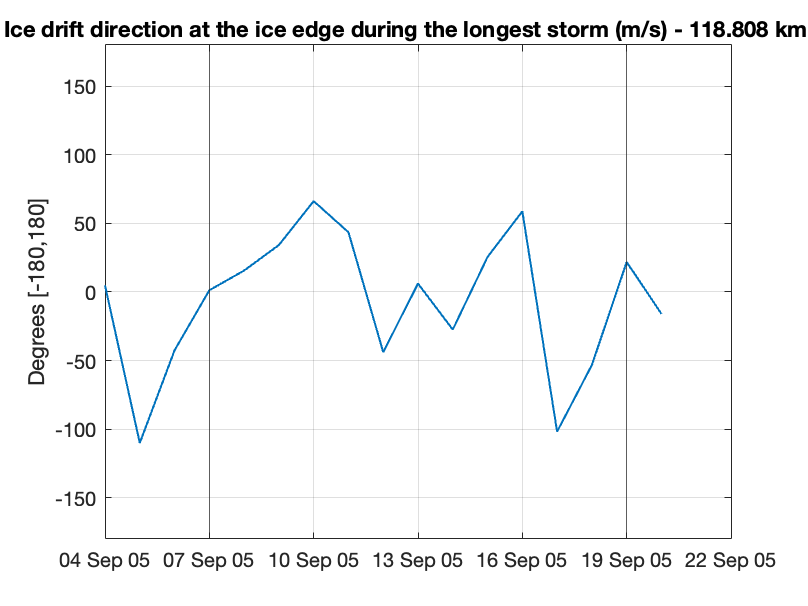


% Ice direction
storm_ts11 = timeseries(ice_direction_hundo_km_in*(360/pi),1:numel(ice_direction_hundo_km_in));
storm_ts11.Name = 'Degrees [-180,180]';
storm_ts11.TimeInfo.Units = 'days';
storm_ts11.TimeInfo.StartDate = char(t1);     % Set start date.
storm_ts11.TimeInfo.Format = 'dd mmm yy';       % Set format for display on x-axis.

fig_count = fig_count + 1;
figure(fig_count)

plot(storm_ts11,'LineWidth',line_width)
title(sprintf('Ice drift direction at the ice edge during the longest storm (m/s) - %g km in', dist_into_miz))
ylim([-180,180])
xline(daybuffer)
xline(storm_end-storm_start-daybuffer)
grid on

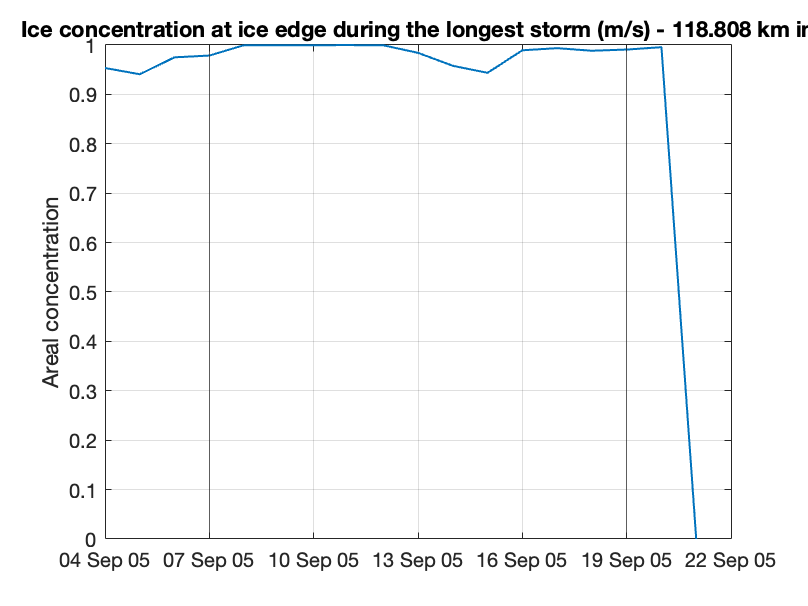



% Aice

storm_ts_aice = timeseries(aice_hundo_km_in,1:numel(aice_hundo_km_in));
storm_ts_aice.Name = 'Areal concentration';
storm_ts_aice.TimeInfo.Units = 'days';
storm_ts_aice.TimeInfo.StartDate = char(t1);     % Set start date.
storm_ts_aice.TimeInfo.Format = 'dd mmm yy';       % Set format for display on x-axis.

fig_count = fig_count + 1;
figure(fig_count)

plot(storm_ts_aice,'LineWidth',line_width)
title(sprintf('Ice concentration at ice edge during the longest storm (m/s) - %g km in', dist_into_miz))
ylim([0,1])
xline(daybuffer)
xline(storm_end-storm_start-daybuffer)
grid on

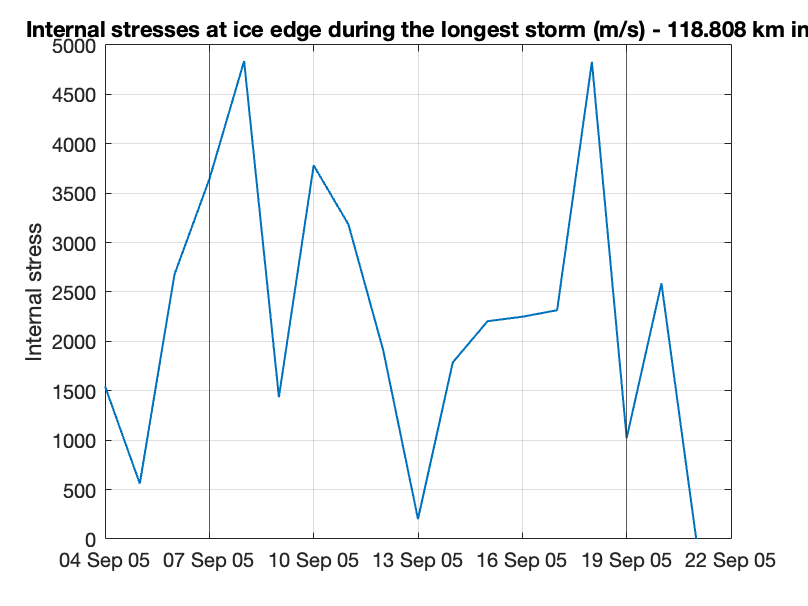



% Internal stress

storm_ts4 = timeseries(sigP_hundo_km_in,1:numel(aice));
storm_ts4.Name = 'Internal stress';
storm_ts4.TimeInfo.Units = 'days';
storm_ts4.TimeInfo.StartDate = char(t1);     % Set start date.
storm_ts4.TimeInfo.Format = 'dd mmm yy';       % Set format for display on x-axis.

fig_count = fig_count + 1;
figure(fig_count)

plot(storm_ts4,'LineWidth',line_width)
title(sprintf('Internal stresses at ice edge during the longest storm (m/s) - %g km in', dist_into_miz))
ylim([0,5000])
xline(daybuffer)
xline(storm_end-storm_start-daybuffer)
grid on

## Movies over storm

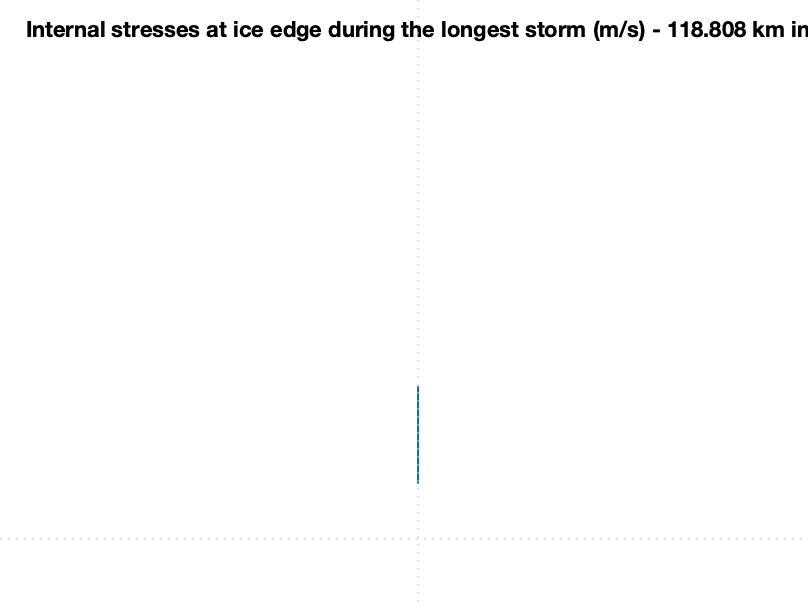

Error using matlab.graphics.axis.decorator.DatetimeRuler/validateLimits
Value must be a 1x2 vector of increasing datetime values.

Error in matlab.graphics.axis.decorator.DatetimeRuler/setLimitsDelegate

Error in tightmap>tightmapOn (line 60)
    set(gca,'XLim',xLimits,'YLim',yLimits)

Error in tightmap (line 32)
        tightmapOn(0.002)

Error in 

variable = ["aice","wave_sig_ht","sigP","fsdrad"];
for j = 1:numel(variable)
    video_name = strcat(variable(j), '_', case_name, '_', '2022_02_16', '.mp4');
    writerObj = VideoWriter(video_name,'MPEG-4');
    time_period = 'd'; %'1','d','m','y'
    datapoints = storm_end-storm_start;
    sector = "SA";
    date_storm = storm_start_date;
    map_type = 'eqaazim'; %cassini
    % set the frame rate to one frame per second
    set(writerObj,'FrameRate',datapoints/5); % 0.5 = 2 seconds per frame
    % open the writer
    open(writerObj);
    ticker = 1;
    
    %% Plotting
    user = 'noahday'; %a1724548, noahday, Noah
    %ssd_dir = '/Users/noahday/Maths1/';%'/Volumes/Noah_SSD/run_data';
    
    for i = 1:max(storm_duration)
       % Get the file name
       filename = strcat('/Volumes/NoahDay5TB/casesmbp/',case_name,"/history/iceh.",date_storm,".nc");
       % Plot the map
       map_creator(filename, date_storm, i, variable(j), grid, sector, user)
       % Update date
       date_storm = update_date(date_storm);
    end    

    % iterate over each image
     for k=1:max(storm_duration)
         % use imread to read the image
         figname = sprintf('frames/image%d.png',k);
         img = imread(figname);
         % resize the imagei_vec
         %img = imresize(img,2);
         % convert the image to a frame using im2frame
         frame = im2frame(img);
         % write the frame to the video
         writeVideo(writerObj,frame);
     end
     % close the writer
     close(writerObj);
end

## 1. Preamble for 2009 only

%% Read in the data.
%clear
%close all
addpath functions
addpath packages/quiverwcolorbar

% Parameters
sector = "SA";
grid = 'gx1';
case_name = 'fixedwaves';
filedir = '/Volumes/NoahDay5TB/casesmbp/fixedwaves';

[lat,lon,row] = grid_read(grid);

% Make sector mask
[len,wid] = size(lat);
fig_count = 0;
coords = sector_coords(sector)

coords =    -45    20
   -65    20
   -45    40
   -65    40



day_init = 1;
month_init = 1;
year_init = 2009;
date_init = sprintf('%d-0%d-0%d', year_init, month_init, day_init);
date = date_init;
max_wind = 10;
min_wind = 5;
min_SIC = 0.15;

## Measuring storm events

%% Read in Data
datapoints = 365; % days from 01/01/2005-31/12/2009 + 1 leap year
date = date_init;
% Take the location to be the centre of the sector
location(1) = (coords(1,1)+coords(2,1))/2;
location(2) = (coords(1,2)+coords(3,2))/2;

[lat_out_north,lon_out] = lat_lon_finder(location(1),location(2),lat,lon); 
[lat_out_south,~] = lat_lon_finder(-80,location(2),lat,lon); 

dim = 2;
for j = 1:datapoints
    filename = strcat(filedir,"/history/iceh.",date,".nc");
    % Find the edge of the MIZ
    variable = "aice";
    aice_data = data_format(filename,variable,row,lat,lon,dim);
    lat_out = lat_out_north;
    for l = lat_out_south:lat_out_north
        if aice_data(lon_out,l) > min_SIC
            ice_edge_pos = l; 
        end
    end
    % Wind speed
    variable = "uatm";
    atm_data_x = data_format(filename,variable,row,lat,lon,dim);
    variable = "vatm";
    atm_data_y = data_format(filename,variable,row,lat,lon,dim);

    atm_x = atm_data_x(lon_out,ice_edge_pos);
    atm_y = atm_data_y(lon_out,ice_edge_pos);

    wind_speed(j) = norm([atm_x,atm_y]);
    wind_direction(j) = atan(atm_y/atm_x);

    date = update_date(date);
end
end_date = date;

## Plotting

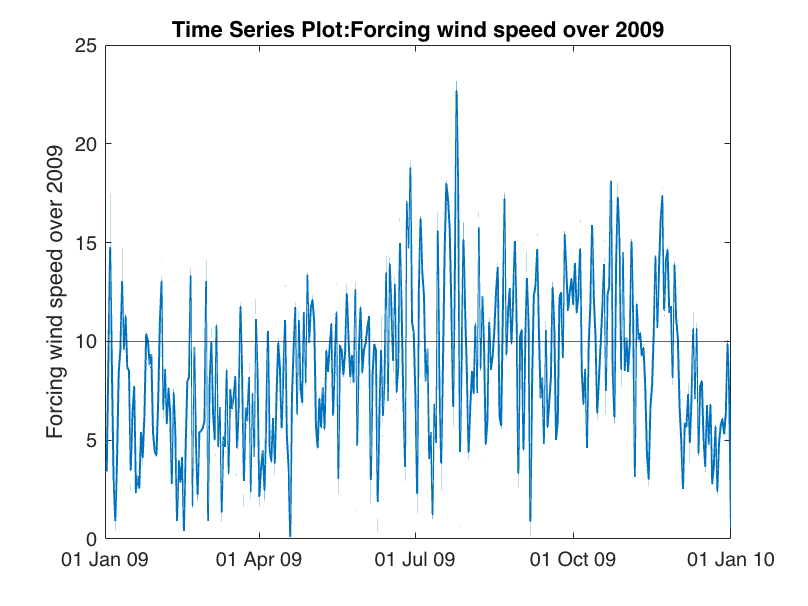

date = end_date;

datapoints = 365;
% Wind speed
t1 = datetime(year_init,month_init,day_init);
t2 = datetime(str2num(end_date(1:4)),str2num(end_date(6:7)),str2num(end_date(9:10)));
dates = datevec(t1:t2);

ts1 = timeseries(wind_speed,1:datapoints);
ts1.Name = 'Forcing wind speed over 2009';
ts1.TimeInfo.Units = 'days';
ts1.TimeInfo.StartDate = char(t1);     % Set start date.
ts1.TimeInfo.Format = 'dd mmm yy';       % Set format for display on x-axis.

ts2 = timeseries(wind_direction,1:datapoints);
ts2.Name = 'Wind direction over 2009';
ts2.TimeInfo.Units = 'days';
ts2.TimeInfo.StartDate = char(t1);     % Set start date.
ts2.TimeInfo.Format = 'dd mmm yy';       % Set format for display on x-axis.


%% Plotting
line_width = 1;

% Wind speed
fig_count = fig_count + 1;
figure(fig_count)
plot(ts1,'LineWidth',line_width)
yline(max_wind)

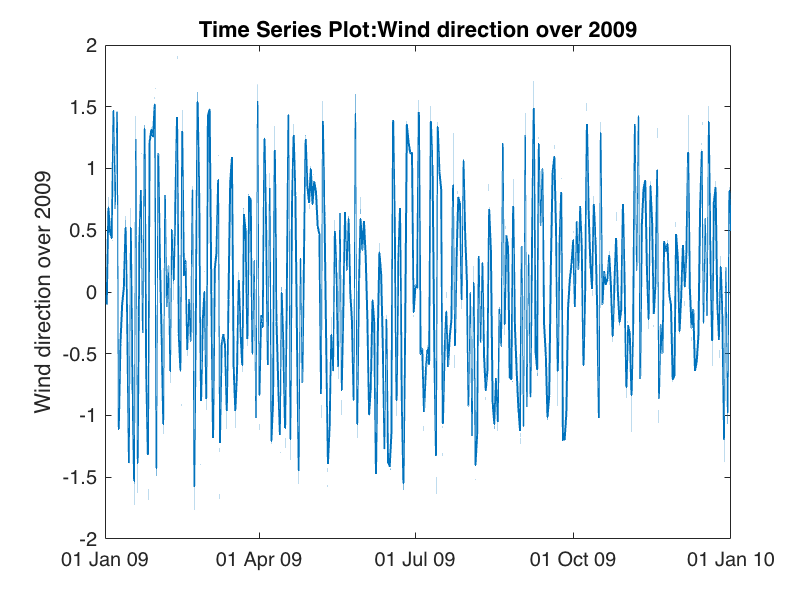


% Wind direction
fig_count = fig_count + 1;
figure(fig_count)
plot(ts2,'LineWidth',line_width)

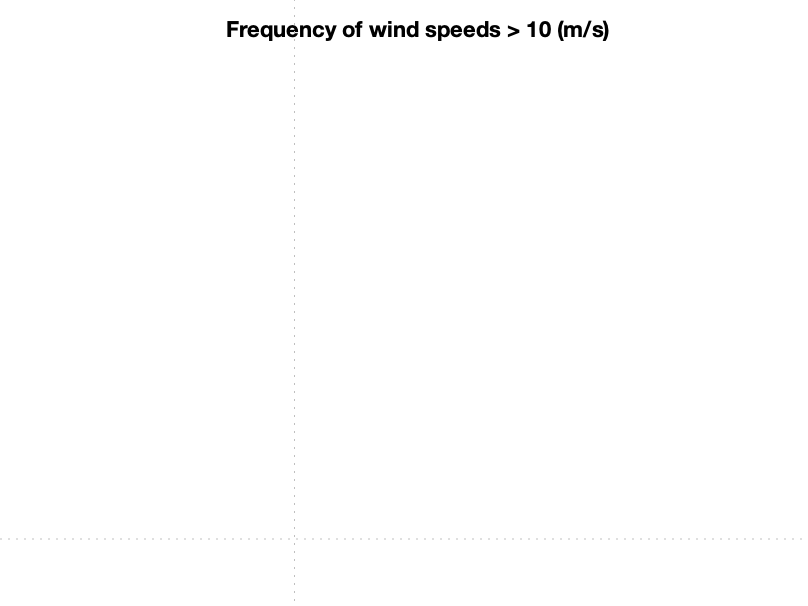


% Storm events
freq_wind = wind_speed > max_wind;


ts3 = timeseries(freq_wind,1:datapoints);
ts3.Name = 'Forcing wind speed';
ts3.TimeInfo.Units = 'days';
ts3.TimeInfo.StartDate = char(t1);     % Set start date.
ts3.TimeInfo.Format = 'dd mmm yy';       % Set format for display on x-axis.

% Wind speed
fig_count = fig_count + 1;
figure(fig_count)
plot(ts3,'LineWidth',line_width)
title(sprintf('Frequency of wind speeds > %g (m/s)',max_wind))
ylim([0,2])

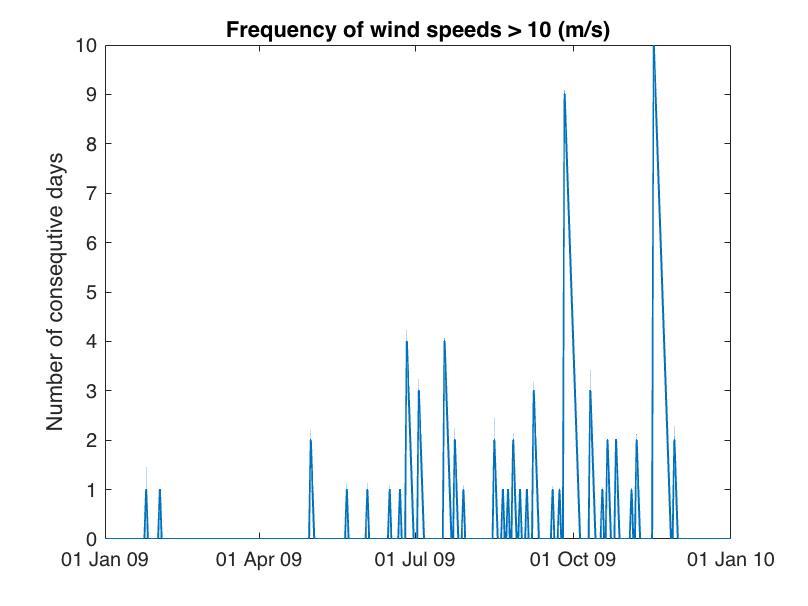


v = numel(freq_wind):-1:1;
ii = [true,diff(freq_wind)~=0];
n = v(ii);
t = [n(2:end)+1,1];
storm_duration = v - t(cumsum(ii));
% remove zeros
storm_duration = storm_duration.*freq_wind;

ts4 = timeseries(storm_duration,1:datapoints);
ts4.Name = 'Number of consequtive days';
ts4.TimeInfo.Units = 'days';
ts4.TimeInfo.StartDate = char(t1);     % Set start date.
ts4.TimeInfo.Format = 'dd mmm yy';       % Set format for display on x-axis.

% Wind speed
fig_count = fig_count + 1;
figure(fig_count)

plot(ts4,'LineWidth',line_width)
title(sprintf('Frequency of wind speeds > %g (m/s)',max_wind))


% Extract the 9 day storm event as it is during winter
storm_duration = storm_duration.*(storm_duration<10);
sprintf('The longest duration of consequential days with winds < %g m/s is %g', max_wind, max(storm_duration))

ans = 'The longest duration of consequential days with winds < 10 m/s is 9'



% TO-DO

% Get the storm for 9 days over the winter (sep)
% Compare this with storm 1
% See how the icepack differs and before and after shots
% Also need to find baselines for both storms
% Compare with the data I have on the notion ( I havent been comparing
% temperatures but this would indicate if its a cyclone (i think))
% Make slides with the before and after of the states
% For each result in the papers do a direct comparison with CICE output







% When is this storm event?

storm_start = find(storm_duration == max(storm_duration));
storm_end = storm_start + max(storm_duration);

date = date_init;
for i = 1:storm_start
    storm_start_date = date;
    date = update_date(date);
end

for i = 1:storm_end-storm_start
    storm_end_date = date;
    date = update_date(date);
end

daybuffer = 3;

t1 = datetime(str2num(storm_start_date(1:4)),str2num(storm_start_date(6:7)),str2num(storm_start_date(9:10))-daybuffer)

t1 = datetime
   22-Sep-2009


t2 = datetime(str2num(storm_end_date(1:4)),str2num(storm_end_date(6:7)),str2num(storm_end_date(9:10))+daybuffer)

t2 = datetime
   07-Oct-2009


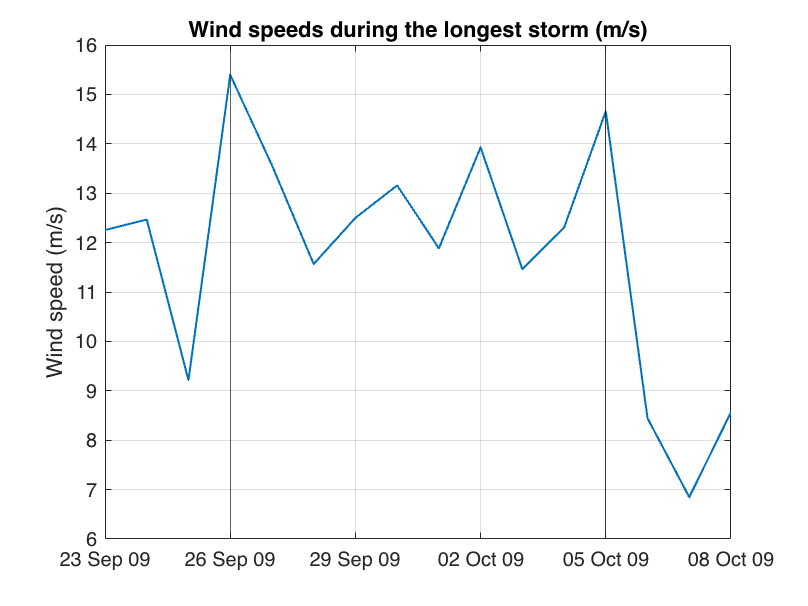




ts5 = timeseries(wind_speed(storm_start-daybuffer:storm_end+daybuffer),1:numel(wind_speed(storm_start-daybuffer:storm_end+daybuffer)));
ts5.Name = 'Wind speed (m/s)';
ts5.TimeInfo.Units = 'days';
ts5.TimeInfo.StartDate = char(t1);     % Set start date.
ts5.TimeInfo.Format = 'dd mmm yy';       % Set format for display on x-axis.


% Wind speed during storm
fig_count = fig_count + 1;
figure(fig_count)
plot(ts5,'LineWidth',line_width)
title('Wind speeds during the longest storm (m/s)')
xline(daybuffer)
xline(storm_end-(storm_start-daybuffer))
grid on

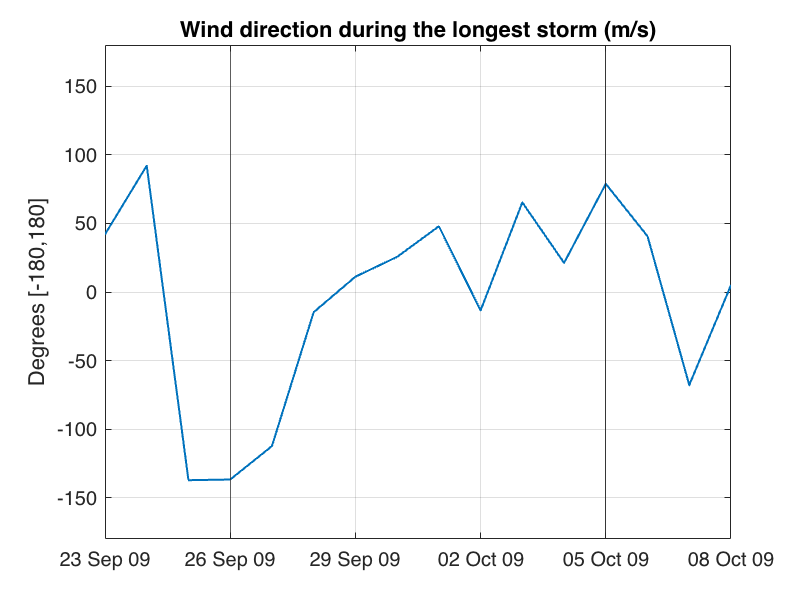


og_storm_start = storm_start;
storm_start = storm_start -daybuffer;
og_storm_end = storm_end;
storm_end = storm_end + daybuffer;

% Regular storm dates
%t1 = datetime(str2num(storm_start_date(1:4)),str2num(storm_start_date(6:7)),str2num(storm_start_date(9:10)))
%t2 = datetime(str2num(storm_end_date(1:4)),str2num(storm_end_date(6:7)),str2num(storm_end_date(9:10)))

storm_direction = wind_direction(storm_start:storm_end).*(360/pi);
ts6 = timeseries(storm_direction,1:numel(storm_direction));
ts6.Name = 'Degrees [-180,180]';
ts6.TimeInfo.Units = 'days';
ts6.TimeInfo.StartDate = char(t1);     % Set start date.
ts6.TimeInfo.Format = 'dd mmm yy';       % Set format for display on x-axis.

% Wind speed during storm
fig_count = fig_count + 1;
figure(fig_count)

plot(ts6,'LineWidth',line_width)
title('Wind direction during the longest storm (m/s)')
ylim([-180,180])
xline(daybuffer)
xline(storm_end-storm_start-daybuffer)
grid on

## Waves during this storm event

date_storm = storm_start_date;
ice_drift_speed = 0;
ice_direction = 0;
sigP = 0;
fsdrad = 0;
swh = 0;
aice = 0;
for j = 1:storm_end-storm_start
    filename = strcat(filedir,"/history/iceh.",date_storm,".nc");
    % Find the edge of the MIZ
    variable = "aice";
    aice_data = data_format(filename,variable,row,lat,lon,dim);
    lat_out = lat_out_north;
    for l = lat_out_south:lat_out_north
        if aice_data(lon_out,l) > min_SIC
            ice_edge_pos = l; 
        end
    end     
    edge_location(j) = lat(lon_out,ice_edge_pos);
    % Drift speed
    variable = "uvel";
    ice_data_x = data_format(filename,variable,row,lat,lon,dim);
    variable = "vvel";
    ice_data_y = data_format(filename,variable,row,lat,lon,dim);

    ice_x = ice_data_x(lon_out,ice_edge_pos);
    ice_y = ice_data_y(lon_out,ice_edge_pos);

    ice_drift_speed(j) = norm([ice_x,ice_y]);

    ice_direction(j) = atan(ice_y/ice_x);

    % Ice concentration
    aice(j) = aice_data(lon_out,ice_edge_pos);

    % Internal stresses
    variable = "sigP";
    sigP_data = data_format(filename,variable,row,lat,lon,dim);
    sigP(j) = sigP_data(lon_out,ice_edge_pos);
    
    % FSD radius
    variable = "fsdrad";
    fsdrad_data = data_format(filename,variable,row,lat,lon,dim);
    fsdrad(j) = fsdrad_data(lon_out,ice_edge_pos);

    % SWH
    variable = "wave_sig_ht";
    swh_data = data_format(filename,variable,row,lat,lon,dim);
    swh(j) = swh_data(lon_out,ice_edge_pos);


    % Look at ~100km into the pack
    hundo_km_in = ice_edge_pos-2;

    ice_x = ice_data_x(lon_out,hundo_km_in);
    ice_y = ice_data_y(lon_out,hundo_km_in);
    ice_drift_speed_hundo_km_in(j) = norm([ice_x,ice_y]);
    ice_direction_hundo_km_in(j) = atan(ice_y/ice_x);
    aice_hundo_km_in(j) = aice_data(lon_out,hundo_km_in);
    sigP_hundo_km_in(j) = sigP_data(lon_out,hundo_km_in);
    fsdrad_hundo_km_in(j) = fsdrad_data(lon_out,hundo_km_in);
    swh_hundo_km_in(j) = swh_data(lon_out,hundo_km_in);

    % Look another ~100 km into the pack
    hundo_km_in = ice_edge_pos-4;

    ice_x = ice_data_x(lon_out,hundo_km_in);
    ice_y = ice_data_y(lon_out,hundo_km_in);
    ice_drift_speed_2hundo_km_in(j) = norm([ice_x,ice_y]);
    ice_direction_2hundo_km_in(j) = atan(ice_y/ice_x);
    aice_2hundo_km_in(j) = aice_data(lon_out,hundo_km_in);
    sigP_2hundo_km_in(j) = sigP_data(lon_out,hundo_km_in);
    fsdrad_2hundo_km_in(j) = fsdrad_data(lon_out,hundo_km_in);
    swh_2hundo_km_in(j) = swh_data(lon_out,hundo_km_in);

    
    data_dates(j) = convertCharsToStrings(date_storm);
    date_storm = update_date(date_storm);
end
pre_storm_post = [ones(1,daybuffer),2*ones(1,storm_end-storm_start-2*daybuffer),3*ones(1,daybuffer)];
T_0 = table(data_dates,ice_drift_speed,ice_direction,aice,sigP,fsdrad,swh,edge_location,pre_storm_post);
T_100 = table(data_dates,ice_drift_speed_hundo_km_in,ice_direction_hundo_km_in,aice_hundo_km_in,sigP_hundo_km_in,fsdrad_hundo_km_in,swh_hundo_km_in,edge_location,pre_storm_post);
T_200 = table(data_dates,ice_drift_speed_2hundo_km_in,ice_direction_2hundo_km_in,aice_2hundo_km_in,sigP_2hundo_km_in,fsdrad_2hundo_km_in,swh_2hundo_km_in,edge_location,pre_storm_post);
T_0 = renamevars(T_0,["data_dates","ice_drift_speed","ice_direction","aice","sigP","fsdrad" ...
    ,"swh","edge_location","pre_storm_post"],["dates", "drift_speed", "drift_direction", "aice","sigP","fsd","edge_location","storm_stages"])
T_100 = renamevars(T_100,["data_dates","ice_drift_speed_hundo_km_in","ice_direction_hundo_km_in","aice_hundo_km_in","sigP_hundo_km_in","fsdrad_hundo_km_in" ...
    ,"swh_hundo_km_in","edge_location","pre_storm_post"],["dates", "drift_speed", "drift_direction", "aice","sigP","fsd","edge_location","storm_stages"])
T_200 = renamevars(T_200,["data_dates","ice_drift_speed_2hundo_km_in","ice_direction_2hundo_km_in","aice_2hundo_km_in","sigP_2hundo_km_in","fsdrad_2hundo_km_in" ...
    ,"swh_2hundo_km_in","edge_location","pre_storm_post"],["dates", "drift_speed", "drift_direction", "aice","sigP","fsd","edge_location","storm_stages"])

## Plotting time series over storm

dist_into_miz = lldistkm([lat(lon_out,ice_edge_pos), lon(lon_out,ice_edge_pos)],[lat(lon_out,ice_edge_pos-2), lon(lon_out,ice_edge_pos-2)]);
dist_into_miz2 = lldistkm([lat(lon_out,ice_edge_pos), lon(lon_out,ice_edge_pos)],[lat(lon_out,ice_edge_pos-4), lon(lon_out,ice_edge_pos-4)]);
%t1 = datetime(str2num(storm_start_date(1:4)),str2num(storm_start_date(6:7)),str2num(storm_start_date(9:10)));
%t2 = datetime(str2num(storm_end_date(1:4)),str2num(storm_end_date(6:7)),str2num(storm_end_date(9:10)));

% Ice drift
storm_ts1 = timeseries(ice_drift_speed,1:numel(ice_drift_speed));
storm_ts1.Name = 'Ice drift speed (m/s)';
storm_ts1.TimeInfo.Units = 'days';
storm_ts1.TimeInfo.StartDate = char(t1);     % Set start date.
storm_ts1.TimeInfo.Format = 'dd mmm yy';       % Set format for display on x-axis.

fig_count = fig_count + 1;
figure(fig_count)

plot(storm_ts1,'LineWidth',line_width)
title('Ice drift speed at the ice edge during the longest storm (m/s)')
ylim([0,0.5])
xline(daybuffer)
xline(storm_end-storm_start-daybuffer)
grid on

% Ice direction
storm_ts2 = timeseries(ice_direction*(360/pi),1:numel(ice_direction));
storm_ts2.Name = 'Degrees [-180,180]';
storm_ts2.TimeInfo.Units = 'days';
storm_ts2.TimeInfo.StartDate = char(t1);     % Set start date.
storm_ts2.TimeInfo.Format = 'dd mmm yy';       % Set format for display on x-axis.

fig_count = fig_count + 1;
figure(fig_count)

plot(storm_ts2,'LineWidth',line_width)
title('Ice drift direction at the ice edge during the longest storm (m/s)')
ylim([-180,180])
xline(daybuffer)
xline(storm_end-storm_start-daybuffer)
grid on

% Aice

storm_ts3 = timeseries(aice,1:numel(aice));
storm_ts3.Name = 'Areal concentration';
storm_ts3.TimeInfo.Units = 'days';
storm_ts3.TimeInfo.StartDate = char(t1);     % Set start date.
storm_ts3.TimeInfo.Format = 'dd mmm yy';       % Set format for display on x-axis.

fig_count = fig_count + 1;
figure(fig_count)

plot(storm_ts3,'LineWidth',line_width)
title(sprintf('Ice concentration at ice edge during the longest storm (m/s) at %g E', lon(lon_out,1)))
ylim([0,1])
xline(daybuffer)
xline(storm_end-storm_start-daybuffer)
grid on

% Internal stress

storm_ts4 = timeseries(sigP,1:numel(aice));
storm_ts4.Name = 'Internal stress';
storm_ts4.TimeInfo.Units = 'days';
storm_ts4.TimeInfo.StartDate = char(t1);     % Set start date.
storm_ts4.TimeInfo.Format = 'dd mmm yy';       % Set format for display on x-axis.

fig_count = fig_count + 1;
figure(fig_count)

plot(storm_ts4,'LineWidth',line_width)
title(sprintf('Internal stresses at ice edge during the longest storm (m/s)',lon(lon_out,1)))
ylim([0,5000])
xline(daybuffer)
xline(storm_end-storm_start-daybuffer)
grid on

% Ice edge location

storm_ts5 = timeseries(ice_edge_data.edge_location,1:numel(ice_edge_data.edge_location));
storm_ts5.Name = 'Latitude';
storm_ts5.TimeInfo.Units = 'days';
storm_ts5.TimeInfo.StartDate = char(t1);     % Set start date.
storm_ts5.TimeInfo.Format = 'dd mmm yy';       % Set format for display on x-axis.

fig_count = fig_count + 1;
figure(fig_count)

plot(storm_ts5,'LineWidth',line_width)
title(sprintf('Location of the ice edge (SIC > %g) at %g E',min_SIC, lon(lon_out,1)))
xline(daybuffer)
xline(storm_end-storm_start-daybuffer)
%ylim([0,5000])
grid on



% 100 km in


%t1 = datetime(str2num(storm_start_date(1:4)),str2num(storm_start_date(6:7)),str2num(storm_start_date(9:10)));
%t2 = datetime(str2num(storm_end_date(1:4)),str2num(storm_end_date(6:7)),str2num(storm_end_date(9:10)));

% Ice drift
storm_ts10 = timeseries(ice_drift_speed_hundo_km_in,1:numel(ice_drift_speed_hundo_km_in));
storm_ts10.Name = 'Ice drift speed (m/s)';
storm_ts10.TimeInfo.Units = 'days';
storm_ts10.TimeInfo.StartDate = char(t1);     % Set start date.
storm_ts10.TimeInfo.Format = 'dd mmm yy';       % Set format for display on x-axis.

storm_ts20 = timeseries(ice_drift_speed_2hundo_km_in,1:numel(ice_drift_speed_hundo_km_in));
storm_ts20.Name = 'Ice drift speed (m/s)';
storm_ts20.TimeInfo.Units = 'days';
storm_ts20.TimeInfo.StartDate = char(t1);     % Set start date.
storm_ts20.TimeInfo.Format = 'dd mmm yy';       % Set format for display on x-axis.


fig_count = fig_count + 1;
figure(fig_count)

plot(storm_ts1,'LineWidth',line_width)
hold on 
plot(storm_ts10,'LineWidth',line_width)
plot(storm_ts20,'LineWidth',line_width)
title(sprintf('Ice drift speed at the ice edge during the longest storm (m/s) - %g E', lon(lon_out,1)))
ylim([0,0.5])
xline(daybuffer)
xline(storm_end-storm_start-daybuffer)
legend('Ice edge','118km in','237 km in')
grid on
hold off

% Ice direction
storm_ts11 = timeseries(ice_direction_hundo_km_in*(360/pi),1:numel(ice_direction_hundo_km_in));
storm_ts11.Name = 'Degrees [-180,180]';
storm_ts11.TimeInfo.Units = 'days';
storm_ts11.TimeInfo.StartDate = char(t1);     % Set start date.
storm_ts11.TimeInfo.Format = 'dd mmm yy';       % Set format for display on x-axis.

fig_count = fig_count + 1;
figure(fig_count)

plot(storm_ts11,'LineWidth',line_width)
title(sprintf('Ice drift direction at the ice edge during the longest storm (m/s) - %g km in', dist_into_miz))
ylim([-180,180])
xline(daybuffer)
xline(storm_end-storm_start-daybuffer)
grid on


% Aice

storm_ts_aice = timeseries(aice_hundo_km_in,1:numel(aice_hundo_km_in));
storm_ts_aice.Name = 'Areal concentration';
storm_ts_aice.TimeInfo.Units = 'days';
storm_ts_aice.TimeInfo.StartDate = char(t1);     % Set start date.
storm_ts_aice.TimeInfo.Format = 'dd mmm yy';       % Set format for display on x-axis.

fig_count = fig_count + 1;
figure(fig_count)

plot(storm_ts_aice,'LineWidth',line_width)
title(sprintf('Ice concentration at ice edge during the longest storm (m/s) - %g km in', dist_into_miz))
ylim([0,1])
xline(daybuffer)
xline(storm_end-storm_start-daybuffer)
grid on


% Internal stress

storm_ts4 = timeseries(sigP_hundo_km_in,1:numel(aice));
storm_ts4.Name = 'Internal stress';
storm_ts4.TimeInfo.Units = 'days';
storm_ts4.TimeInfo.StartDate = char(t1);     % Set start date.
storm_ts4.TimeInfo.Format = 'dd mmm yy';       % Set format for display on x-axis.

fig_count = fig_count + 1;
figure(fig_count)

plot(storm_ts4,'LineWidth',line_width)
title(sprintf('Internal stresses at ice edge during the longest storm (m/s) - %g km in', dist_into_miz))
ylim([0,5000])
xline(daybuffer)
xline(storm_end-storm_start-daybuffer)
grid on

## Movies over storm

variable = ["aice","wave_sig_ht","sigP","fsdrad"];
for j = 1:numel(variable)
    video_name = strcat(variable(j), '_', case_name, '_', '2022_02_16', '.mp4');
    writerObj = VideoWriter(video_name,'MPEG-4');
    time_period = 'd'; %'1','d','m','y'
    datapoints = storm_end-storm_start;
    sector = "SA";
    date_storm = storm_start_date;
    map_type = 'eqaazim'; %cassini
    % set the frame rate to one frame per second
    set(writerObj,'FrameRate',datapoints/5); % 0.5 = 2 seconds per frame
    % open the writer
    open(writerObj);
    ticker = 1;
    
    %% Plotting
    user = 'noahday'; %a1724548, noahday, Noah
    %ssd_dir = '/Users/noahday/Maths1/';%'/Volumes/Noah_SSD/run_data';
    
    for i = 1:max(storm_duration)
       % Get the file name
       filename = strcat('/Volumes/NoahDay5TB/casesmbp/',case_name,"/history/iceh.",date_storm,".nc");
       % Plot the map
       map_creator(filename, date_storm, i, variable(j), grid, sector, user)
       % Update date
       date_storm = update_date(date_storm);
    end    

    % iterate over each image
     for k=1:max(storm_duration)
         % use imread to read the image
         figname = sprintf('frames/image%d.png',k);
         img = imread(figname);
         % resize the imagei_vec
         %img = imresize(img,2);
         % convert the image to a frame using im2frame
         frame = im2frame(img);
         % write the frame to the video
         writeVideo(writerObj,frame);
     end
     % close the writer
     close(writerObj);
end

## Functions

function sector_data = data_format_sector(filedir,variable,sector,dim)
     if ~exist('dim', 'var')
        dim = 2; 
     end

    % Grid
    grid = "gx1";
    [lat,lon,row] = grid_read(grid);
    % Read in data
    data = data_format(filedir,variable,row,lat,lon,dim);
    ocean_mask = data_format(filedir,'tmask',row,lat,lon);
    % Coordinates
    coords = sector_coords(sector); % (NW;NE;SW;SW) (lat,lon)
    for i = 1:4
        [lat_out(i),lon_out(i)] = lat_lon_finder(coords(i,1),coords(i,2),lat,lon);
    end
    [len,wid] = size(data);
    sector_data = zeros(len,wid);
    sector_mask = false(len,wid);
    sector_data = ~ocean_mask*NaN;
    for i = 0:lat_out(1)-lat_out(2)
        sector_mask(lon_out(1):lon_out(3), lat_out(1)-i:lat_out(3)) = true;
        sector_data(lon_out(1):lon_out(3), lat_out(1)-i:lat_out(3)) = data(lon_out(1):lon_out(3), lat_out(1)-i:lat_out(3));
    end
    
end

function name = sector_name(sector)
    if sector == "SA"
        name = "South African Antarctic";
    elseif sector == "WS"
        name = "Weddell Sea";
    elseif sector == "EA"
        name = "East Antarctic";
    else
        name = "";
        
    end
end

